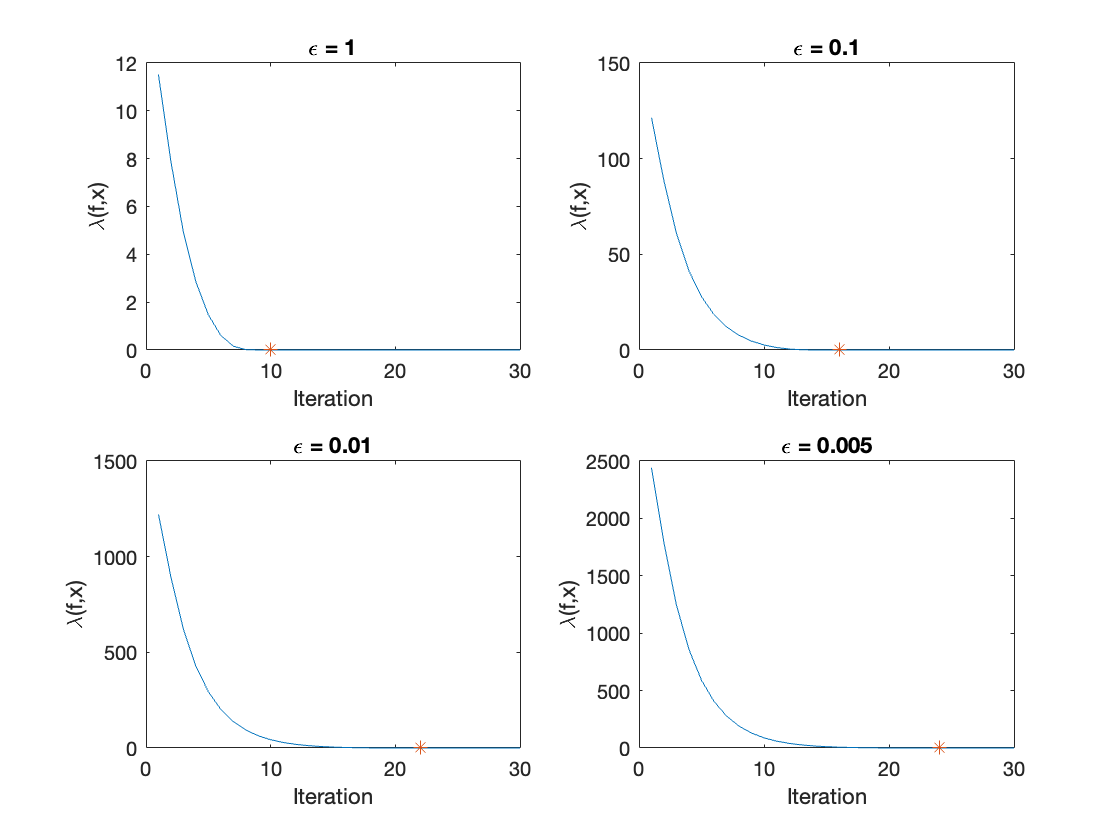

clear;clc;
foo = @(epsilon, x) sum((1:10).*x)/epsilon - sum(log(1-x.^2));
grad_x = @(epsilon, x) (1:10)/epsilon - (1./(1+x) - 1./(1-x));
Hess_x = @(x) (1+x).^(-2) + (1-x).^(-2);
lambda_fx = @(epsilon, x) sqrt(sum(grad_x(epsilon, x).^2 .* (1./Hess_x(x))));
epsilon = [1; 0.1; 0.01; 0.005];
max_iter = 30;
record = zeros(4, max_iter);
record_iter = 1:4;


for ind = 1:4
    iter = 0;
    xt_1 = 0;
    xt   = 0;
    running_epsilon = epsilon(ind);
    running_lambda = lambda_fx(running_epsilon, xt_1);
    while running_lambda > 1e-6
        iter = iter + 1;
        %disp(["Ind: ", num2str(ind), "iter: ", num2str(iter), "lambda: ", num2str(running_lambda)]);
        xt = xt_1 - 1/(1+running_lambda) .* (1./Hess_x(xt_1)) .* grad_x(running_epsilon, xt_1);
        running_lambda = lambda_fx(running_epsilon, xt);
        record(ind, iter) = running_lambda; 
        xt_1 = xt;
    end
    record_iter(ind) = iter;
end

% record visualization
figure;
subplot(221);
plot(record(1,:));
hold on;
plot(record_iter(1), 0, '*');
title("\epsilon = 1");
ylabel("\lambda(f,x)");
xlabel("Iteration");

subplot(222);
plot(record(2,:));
hold on;
plot(record_iter(2), 0, '*');
title("\epsilon = 0.1");
ylabel("\lambda(f,x)");
xlabel("Iteration");

subplot(223);
plot(record(3,:));
hold on;
plot(record_iter(3), 0, '*');
title("\epsilon = 0.01");
ylabel("\lambda(f,x)");
xlabel("Iteration");

subplot(224);
plot(record(4,:));
hold on;
plot(record_iter(4), 0, '*');
title("\epsilon = 0.005");
ylabel("\lambda(f,x)");
xlabel("Iteration");